load ex7data2.mat

plot(X(:, 1), X(:, 2), 'bo')
hold on


%taking k=3
iterations = 150;
k = randi([0, size(X, 1)], 3, 1);
centroids = [X(k(1), :); X(k(2), :); X(k(3), :)]
for i=1:iterations
    closest = find_closest(X, centroids);
    centroids = average_centroids(X, closest, centroids);
end
points = {};
for i=1:3
    points{i} = find(closest == i);
end
p1 = X(points{1}(:), :);
plot(p1(:, 1), p1(:, 2), 'ro')
hold on
p2 = X(points{2}(:), :);
plot(p2(:, 1), p2(:, 2), 'yo')
hold on
p3 = X(points{3}(:), :);
plot(p3(:, 1), p3(:, 2), 'bo')
hold on
plot(centroids(:, 1), centroids(:, 2), 'gx')
hold off

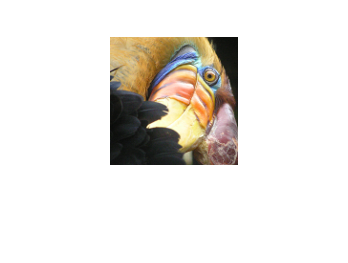

img = double(imread('bird_small.png'));
img = img/255;
imshow(img)

X = reshape(img, size(img, 1) * size(img, 2), 3);
iterations = 10;
k = randi([0, size(X, 1)], 16, 1);
centroids = [];
for i=1:size(k,1)
    centroids = [centroids; X(k(i), :)];
end
%centroids = [X(k(1), :); X(k(2), :); X(k(3), :)]
%history = zeros(size(centroids, 1), iterations);
for i=1:iterations
    closest = find_closest(X, centroids);
    centroids = average_centroids(X, closest, centroids);
end

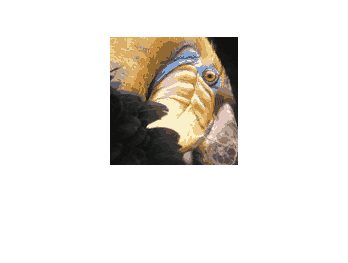

new_img = [];
for i=1:size(closest, 1)
    new_img = [new_img;centroids(closest(i), :)];
end
final = reshape(new_img, size(img, 1), size(img, 2), 3);
imshow(final)

pca

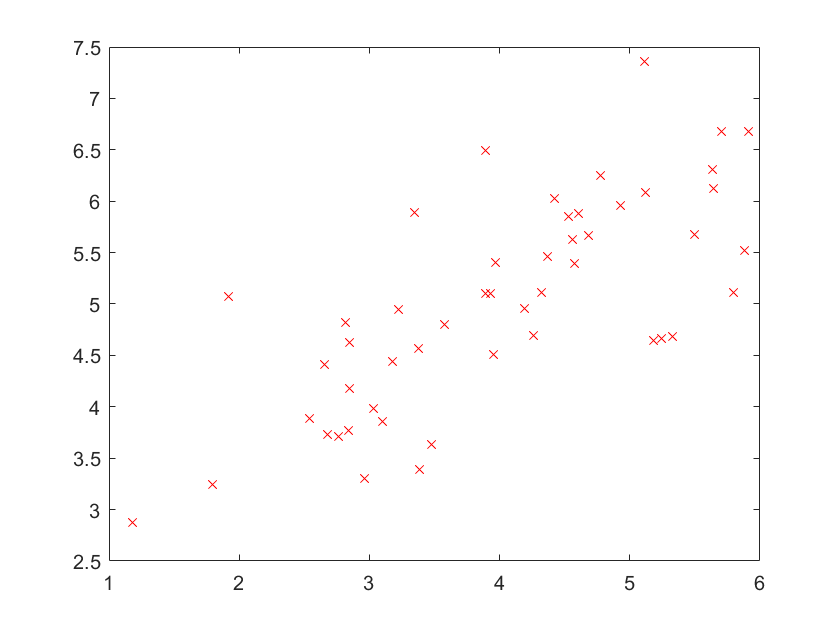

load ex7data1.mat
plot(X(:, 1), X(:, 2), 'rx')

%feature normalization
X_new = bsxfun(@minus, X, mean(X))%substract mean of column elements from corresponding columns

X_new =    -0.6077   -1.6137
    0.5386    0.8514
   -1.3336   -0.5908
   -1.2240   -1.2874
   -1.1427   -0.8273
   -0.0986    1.4856
   -0.5135   -1.3700
    1.9220    1.6780
   -0.0604    0.0956
    0.5726    0.6205


X = bsxfun(@rdivide, X_new, std(X))%divide the std deviation of respective column elements

X =    -0.5181   -1.5768
    0.4592    0.8319
   -1.1369   -0.5773
   -1.0435   -1.2579
   -0.9741   -0.8084
   -0.0840    1.4516
   -0.4377   -1.3386
    1.6385    1.6396
   -0.0515    0.0935
    0.4881    0.6063


covarianceMat = (1/size(X, 1))*X'*X;
[u,s,v] = svd(covarianceMat);

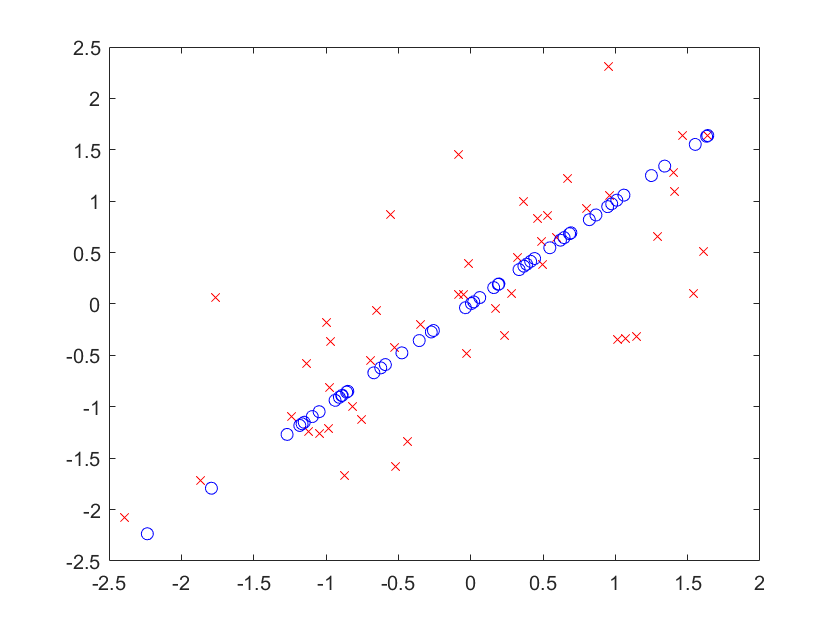

k = 1;
Ured = u(:, 1:k);
Xnew = X*Ured;
Xpred = Xnew*Ured';
plot(X(:, 1), X(:, 2), 'rx')
hold on
plot(Xpred(:, 1), Xpred(:, 2), 'bo')
hold off

load ex7faces.mat
Xorg = X;
X_new = bsxfun(@minus, X, mean(X))%substract mean of column elements from corresponding columns

X_new =   -16.1258  -25.0572  -34.1592  -33.2884  -23.1314  -17.0496  -32.2590  -23.8692  -11.3014    0.6846   -0.0118  -12.0572  -19.8484  -24.5254  -14.3104  -14.5766  -25.5300  -61.3762 -101.2356 -102.5386 -100.0358  -99.4452  -98.7138  -93.7730  -62.8016  -34.7828  -29.7684  -30.4880  -35.6636  -65.2084  -71.9482  -56.9634  -12.0308  -20.9416  -26.7108  -26.2544  -16.1336    3.2030  -48.2814  -32.5058  -21.1914  -32.3292  -37.3132  -35.5606  -39.2432  -27.1334   -7.5658  -14.1056  -19.1472  -28.1908
   29.8742   19.9428   10.8408    2.7116   -0.1314   -0.0496   -0.2590   -7.8692  -31.3014  -20.3154  -14.0118  -16.0572  -15.8484  -12.5254  -13.3104  -15.5766  -18.5300  -21.3762  -17.2356   -1.5386    2.9642  -11.4452  -11.7138   -8.7730  -10.8016  -10.7828   -8.7684   -5.4880   -3.6636   -3.2084   -2.9482   -1.9634   30.9692   22.0584   12.2892    4.7456    2.8664    6.2030    9.7186    6.4942  -24.1914  -24.3292   -8.3132  -10.5606  -15.2432  -14.1334  -11.5658  -12.1056  -13.1472 

X = bsxfun(@rdivide, X_new, std(X))%divide the std deviation of respective column elements

X =    -0.3152   -0.4975   -0.6905   -0.6805   -0.4788   -0.3556   -0.6765   -0.5013   -0.2374    0.0144   -0.0002   -0.2577   -0.4271   -0.5284   -0.3082   -0.3127   -0.5455   -1.2937   -2.0942   -2.0920   -2.0081   -1.9562   -1.9172   -1.7930   -1.1763   -0.6419   -0.5398   -0.5441   -0.6262   -1.1334   -1.2265   -0.9594   -0.2447   -0.4334   -0.5630   -0.5601   -0.3481    0.0701   -1.0701   -0.7195   -0.4699   -0.7173   -0.8367   -0.8096   -0.9019   -0.6290   -0.1757   -0.3257   -0.4393   -0.6383
    0.5839    0.3960    0.2191    0.0554   -0.0027   -0.0010   -0.0054   -0.1653   -0.6576   -0.4274   -0.2954   -0.3432   -0.3410   -0.2699   -0.2867   -0.3341   -0.3959   -0.4506   -0.3565   -0.0314    0.0595   -0.2251   -0.2275   -0.1677   -0.2023   -0.1990   -0.1590   -0.0979   -0.0643   -0.0558   -0.0503   -0.0331    0.6299    0.4565    0.2590    0.1012    0.0618    0.1358    0.2154    0.1437   -0.5364   -0.5398   -0.1864   -0.2404   -0.3503   -0.3276   -0.2686   -0.2796   -0.3017   -0

covarianceMat = (1/size(X, 1))*X'*X;
[u,s,v] = svd(covarianceMat);

k = 100;
Ured = u(:, 1:k);
Xnew = X*Ured;
Xpred = Xnew*Ured';

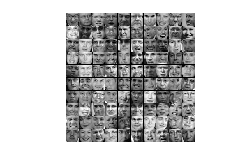

colormap(gray);

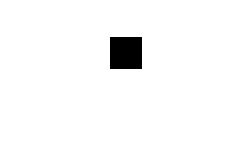

imshow(reshape(Xpred(2, :), 32,32), gray)

imshow(reshape(X(2, :), 32,32), gray)

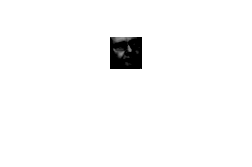

imshow(reshape(Xorg(2, :), 32,32), gray)
displayData(Xorg(1:100, :));

function closest = find_closest(X, centroids)
    closest = zeros(size(X, 1), 1);
    for i=1:size(X, 1)
        distances = distance(centroids', X(i, :)');
        [~, closest(i)] = min(distances);
    end
end

function centroids = average_centroids(X, closest, centroids)
    for i=1:size(centroids, 1)
        points = find(closest == i);
        %centroids;
        %centroids(i) = (1/size(points))*sum(distance(X(points, :)', 0));
        center = sum(X(points, :))/size(points, 1);
        centroids(i, :) = center;
    end
end

function distance1 = distance(point1, point2)
    distance1 = sum((point1 - point2).^2);
end